clear all

## Defining variables

syms m1 g m2 M L1 L2 x dx 
m1 = 100;
m2 = 100;
M = 1000;
L1 = 20;
L2 = 10;
g = 9.81;
tspan = 0:0.1:100;
% q = [x dx t1 dt1 t2 dt2];
%Enter initial conditions
X0 = [0,0,deg2rad(-20),0,deg2rad(30),0,0,0,0,0,0,0];

## Linearized Model

A = [0 1 0 0 0 0; 0 0 -m1*g/M 0 -m2*g/M 0; 0 0 0 1 0 0; 0 0 -((M*g)+(m1*g))/(M*L1) 0 -g*m2/(M*L1) 0; 0 0 0 0 0 1; 0 0 -m1*g/(M*L2) 0 -((M*g)+(m2*g))/(M*L2) 0];
B = [0; 1/M; 0; 1/(L1*M); 0; 1/(L2*M)];
C1 = [1 0 0 0 0 0; 0 0 0 0 0 0; 0 0 0 0 0 0];
d = [1;0;0];
sys1 = ss(A,B,C1,d);

## LQR Controller

Q = [1/12 0 0 0 0 0;
    0 1/(12*0.1) 0 0 0 0;
    0 0 1/(8*0.2^2) 0 0 0;
    0 0 0 1/(12*0.01^2) 0 0;
    0 0 0 0 1/(8*0.2^2) 0;
    0 0 0 0 0 1/(12*0.01^2)];

R = 0.00001;

[K,S,P] = lqr(A,B,Q,R);

sys = ss(A-B*K,B,C1,d);

poles=[-3;-6;-9;-12;-15;-18];

L1 = place(A',C1',poles)';

## Kalman Estimator Design

vd=0.3*rand(1)*eye(6);          %Process Noise
vn=0.1*rand(1);                   %Measurement Noise
Ac1 = A-(L1*C1);
e_sys1 = ss(Ac1,[B L1],C1,0);

## Non-linear Model LQG Response

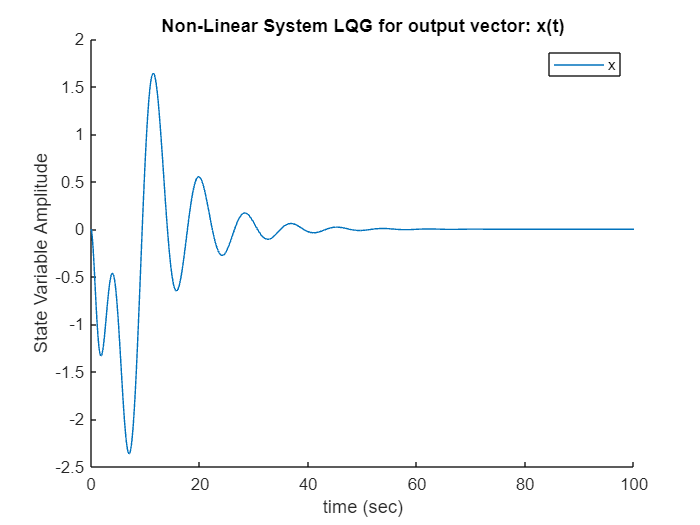

[t,X1] = ode45(@(t,X)nLinearLQG(t,X,C1,vd,vn),tspan,X0);
figure();
hold on
plot(t,X1(:,1))
ylabel('State Variable Amplitude')
xlabel('time (sec)')
title('Non-Linear System LQG for output vector: x(t)')
legend('x')
hold off

## Non-linear LQG function

function dX = nLinearLQG(t,X,C,vd,vn)

M=1000; 
m1=100;
m2=100;
l1=20;
l2=10;
g=9.81;

A=[0 1 0 0 0 0; 
    0 0 -(m1*g)/M 0 -(m2*g)/M 0;
    0 0 0 1 0 0;
    0 0 -((M+m1)*g)/(M*l1) 0 -(m2*g)/(M*l1) 0;
    0 0 0 0 0 1;
    0 0 -(m1*g)/(M*l2) 0 -(g*(M+m2))/(M*l2) 0];

B=[0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];

Q = [1/12 0 0 0 0 0;
    0 1/(12*0.1) 0 0 0 0;
    0 0 1/(8*0.2^2) 0 0 0;
    0 0 0 1/(12*0.01^2) 0 0;
    0 0 0 0 1/(8*0.2^2) 0;
    0 0 0 0 0 1/(12*0.01^2)];

R = 0.00001;

D = 0;

K_val = lqr(A,B,Q,R);
F=-K_val*X(1:6);

% poles=[-3;-6;-9;-12;-15;-18];
% 
% L = place(A',C',poles)';
% 
% temp = (A-L*C)*X(7:12);

K_del=lqr(A',C',vd,vn)';

sd =(A-K_del*C)*X(7:12);

dX=zeros(12,1);

dX(1) = X(2);
dX(2)=(F-(g/2)*(m1*sin(2*X(3))+m2*sin(2*X(5)))-(m1*l1*(X(4)^2)*sin(X(3)))-(m2*l2*(X(6)^2)*sin(X(5))))/(M+m1*((sin(X(3)))^2)+m2*((sin(X(5)))^2));%xDD
dX(3)= X(4);
dX(4)= (dX(2)*cos(X(3))-g*(sin(X(3))))/l1';
dX(5)= X(6);
dX(6)= (dX(2)*cos(X(5))-g*(sin(X(5))))/l2;
dX(7)= sd(1);
dX(8)= sd(2);
dX(9)= sd(3);
dX(10)= sd(4);
dX(11)= sd(5);
dX(12)= sd(6);

end